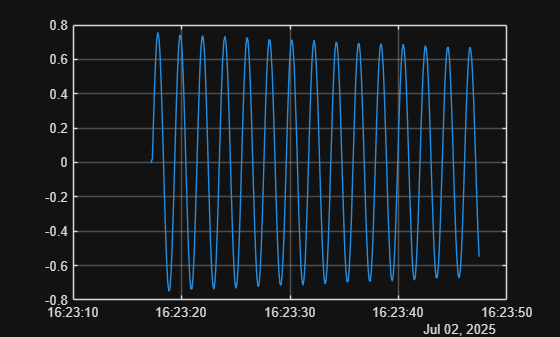

clear
clc
% tau calculations for the platofrm
file_platform = "C:\Users\Jordan Baylos\Desktop\eVTOL Trifilar\DUST 4 Trifiler MOI Calculations\DUST 4 Trifiler Raw Data\Sensor off Axis\TrifilierTestData_Empty_OffAxis3.mat";
load(file_platform)
x_platform =  AngularVelocity.Timestamp;
y_platform = AngularVelocity.Z;
plot(x_platform,y_platform)
grid on

peaks_platform = findpeaks(y_platform);
% Adjust this value based off the data you see on the graph
peak_threshold_platform = 0.6;
[pks,locs] = findpeaks(y_platform,'MinPeakHeight',peak_threshold_platform);
peak_times_platform = x_platform(locs);
period_platform = seconds(diff(peak_times_platform));
mean_period_platform = mean(period_platform) %this is the tau of the platform

mean_period_platform = 2.0570

frequency_platform = 1./period_platform;
mean_frequency_platform = mean(frequency_platform)

mean_frequency_platform = 0.4864

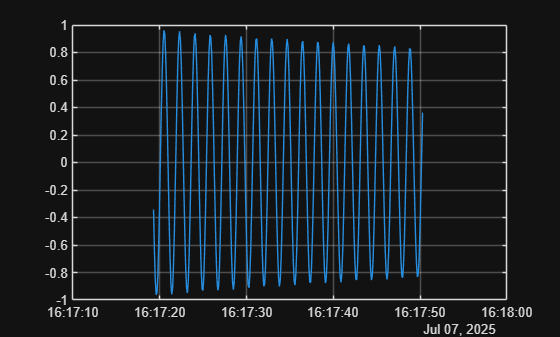

% tau calculations for the component
file_component = "C:\Users\Jordan Baylos\Desktop\eVTOL Trifilar\DUST 4 Trifiler MOI Calculations\DUST 4 Trifiler Raw Data\Sensor off Axis\Battery_zaxis.mat";
load(file_component)
x_component = AngularVelocity.Timestamp;
y_component = AngularVelocity.Z;
plot(x_component, y_component);
grid on;

peaks_component = findpeaks(y_component);
% Adjust this value based off the data you see on the graph
peak_threshold_component = 0.4;
[pks_component, locs_component] = findpeaks(y_component, 'MinPeakHeight', peak_threshold_component);
peak_times_component = x_component(locs_component);
period_component = seconds(diff(peak_times_component));
mean_period_component = mean(period_component) % this is the tau of the component

mean_period_component = 1.7688

frequency_component = 1./period_component;
mean_frequency_component = mean(frequency_component)

mean_frequency_component = 0.5657

R = 29.5/12; %ft, this is the distance from the cables to the cg of the rotating platform
g = 32.2; %ft/s^2
tau_platform = mean_period_platform;
tau_component = mean_period_component;
L = (128)/12; %ft
Mass_of_component = 5.36/32.2; %slugs
Mass_of_platform = 0.4103 +   0.0116; %slugs, mass of platfrom + mass of phone

% Moment of Inertia Calculations
[I_platform] = Ixyz_platform(R, g, tau_platform, L, Mass_of_platform)

I_platform = 0.8249

[I_component] = Ixyz_Trifilar(R, g, tau_component, L,Mass_of_component ,Mass_of_platform,I_platform) %slug-ft^2

I_component = 0.0257

% function for the moment of inertia of the platform
function [I_platform] = Ixyz_platform(R, g, tau_platform, L, Mass_of_platform)
I_platform = (R^2*g*tau_platform^2)/(4*pi^2*L)*(Mass_of_platform);
end

% function for the moment of inertia calculations of the component
function [I_component] = Ixyz_Trifilar(R, g, tau_component, L, Mass_of_component,Mass_of_platform,I_platform)
I_component = (R^2*g*tau_component^2)/(4*pi^2*L)*(Mass_of_component + Mass_of_platform) - I_platform;
end